clear all;
close all; 
 


% data1 = readmatrix('albuminData.csv'); 
data1 = readmatrix('Data/PCR_data.csv');

calibrationData = readmatrix('Calibrate/calibrationData.csv');


%signal Data
spec_data = data1(:, 2:end);
%max value of data to normalize
mVal = max(max(spec_data))

mVal = 85

spec_data1 = spec_data./mVal + calibrationData;

% spec_data = data2(:, 2:end);
% %max value of data to normalize
% mVal = max(max(spec_data))
% spec_data2 = spec_data./mVal + calibrationData;

data = [data1(:, 1),spec_data1 ];%; data2(:, 1),spec_data2 ]
data = sortrows(data, 1, "ascend");
spec_data = data(:, 2:end);
%label Data
% lData = data(:, 1);
%label for ACR
lData = data(:, 1)./160.0;



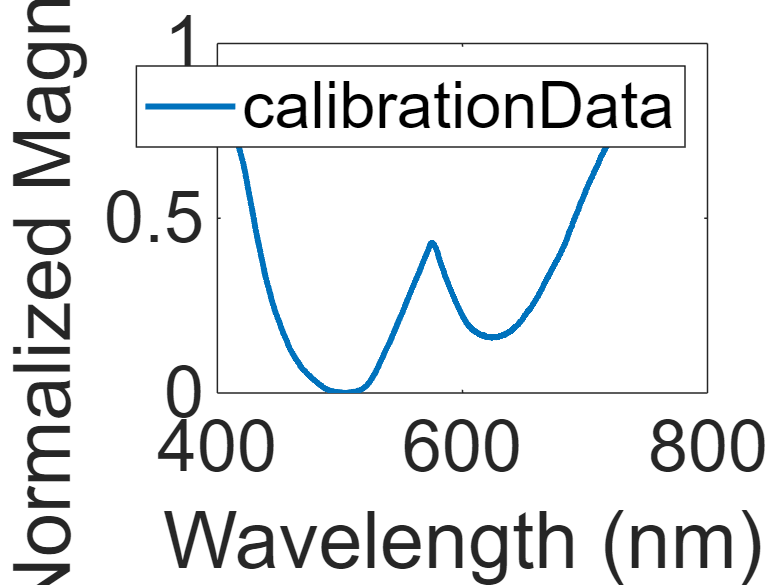


y = length(spec_data(1, :));
x = length(lData);
t = (1:y); 

wv = linspace(400, 750, y);

createFigure(wv, calibrationData, "calibrationData")

sData = zeros(x, y);
%order= 11; 
%window = 25;
order= 9; 
window = 21;
for i = 1:x
    p = spec_data(i, :);
    p = smoothdata(p, 'movmedian', window);
    p = sgolayfilt(p, order, window);
    sData(i, :) = p; 
end



ul = -1;
samp = 50;
ppm = unique(lData);
for i = 1:length(ppm)
    tmp = num2str(ppm(i)) + " UPCR";
%     tmp = num2str(ppm(i)) + " mg/dL";
    labels(i) = {tmp};
end

nConditions = length(labels); 
indeces = zeros(0, nConditions);
lbls = zeros(0, nConditions);
j = 1; 



for i=1:x
    if(lData(i) ~= ul)
        ul = lData(i);
        l = lData(i) / 200.0;
        lbls(j) = l;
        indeces(j) = i;
        j = j+1;
    end
end



 endInx = {}; 
 for i=1:nConditions
     if(i ~= nConditions)
         a = indeces(i);
         b = indeces(i+1)-1;
         endInx{i} = [a:b];
     else
         a = indeces(i);
         b = x;
         endInx{i} = [a:b];
     end
 end



[Xsorted,I] = sort(lbls);
indeces = indeces(I);
endInx = endInx(I);

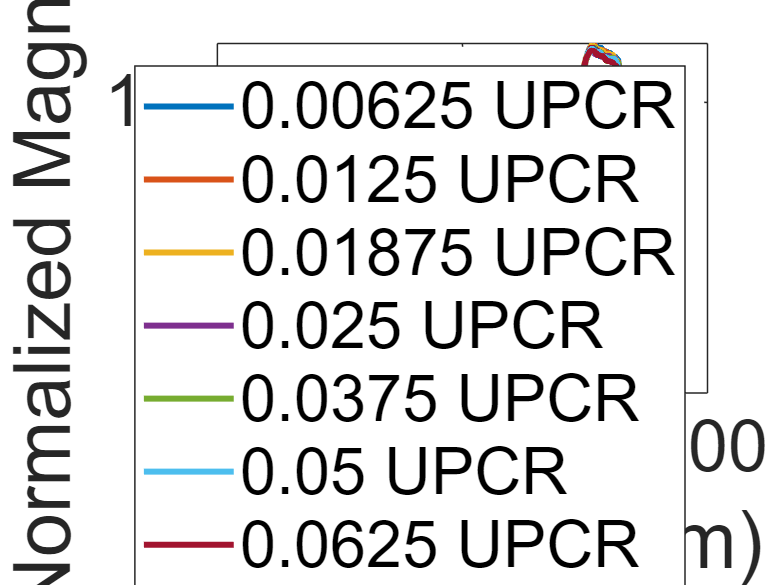

a2plot = sData(indeces, :);

createFigure(wv, a2plot, labels);

%%Summary Stats per class
m = max(max(sData));

stdData = zeros(nConditions, y);
% skewData = zeros(nConditions, y);
% kurtData = zeros(nConditions, y);
j = j; 
for i=1:nConditions
    for j = 1:y
        stdData(i, j) = std(sData(endInx{i},j)./m);
%         skewData(i, j) = skewness(sData(endInx{i},j));
%         kurtData(i, j) = kurtosis(sData(endInx{i},j));
    end
end

%a2plot = stdData;
%createFigure(wv, a2plot, labels);



sdData_all = zeros(1, y);
for i = 1:y
    sdData_all(i) = std(sData(:,i))/m;
end

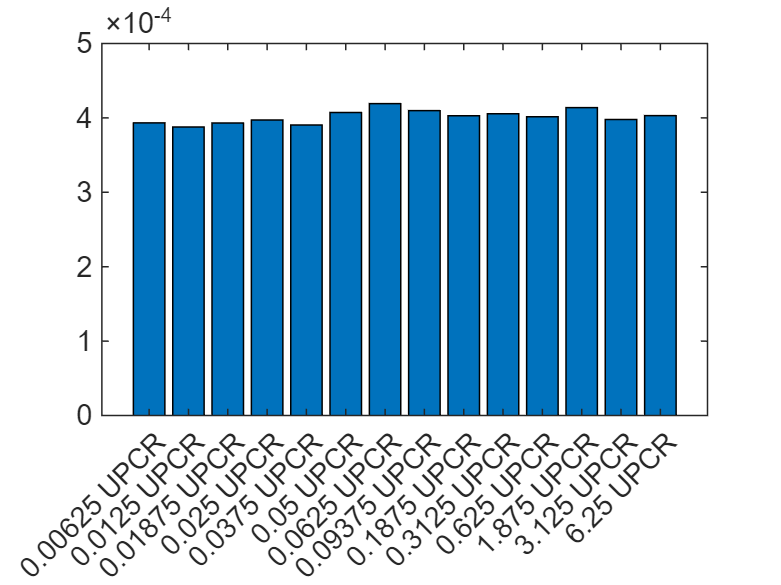

aveSD = mean(stdData, 2);
bar(1:nConditions,aveSD)
set(gca,'xticklabel',labels)

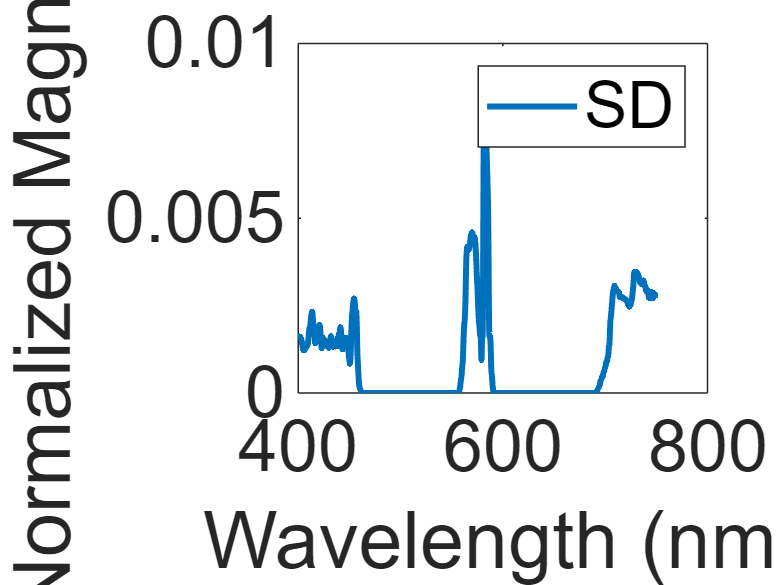

aveSD_all = mean(aveSD);

dl = {'SD'};
a2plot = sdData_all;
createFigure(wv, a2plot, dl);

pData = zeros(x, y);
 
for i = 1:x
   p = sData(i, :);
   [xp, yp] = prepareCurveData( t, p );
  
   [p,s,mu] = polyfit(xp,yp,21);
   pData(i, :) = polyval(p,t,[],mu);
end



% a2plot = pData(indeces, :);
% createFigure(wv, a2plot, labels);

% standard normal varient
% mean centers and divides by std of each spectra
 snvData = zeros(x, y);
 windowSize = 75; 
 order = 3; 
 for i = 1:x
     p = pData(i, :);
     p = sgolayfilt(p, order, windowSize);
     p = smoothdata(p, 'movmedian', windowSize);
     snv = SNV(p);
     snvData(i, :) = snv;
end


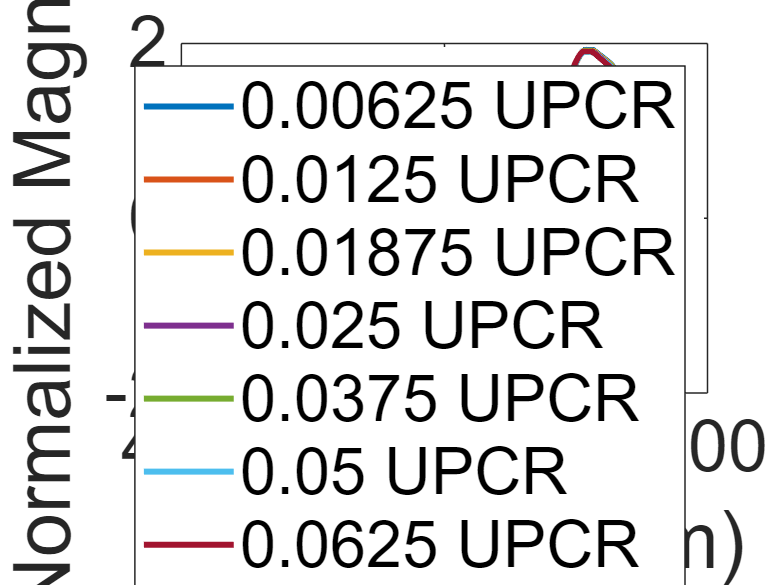


a2plot = snvData(indeces, :);
createFigure(wv, a2plot, labels);

%numerial gradient to get first derivative 
dxData = zeros(x, y);
windowSize = 75; 
order = 3; 

for i = 1:x
    p = snvData(i, :);
    d = smoothdata(p, 'movmedian', windowSize);
    dx = gradient(p);
    dx = sgolayfilt(dx, order, windowSize);
    dx = smoothdata(dx, 'movmedian', windowSize);
    dxData(i, :) = dx;
end


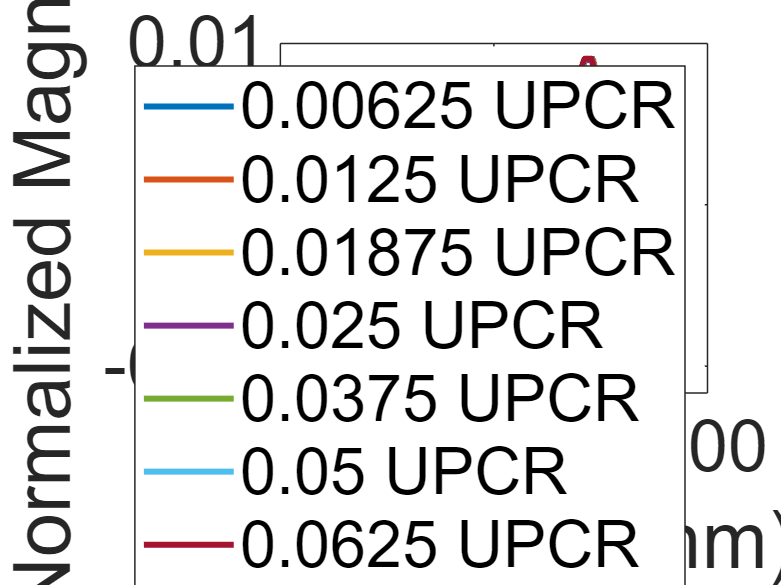


a2plot = dxData(indeces, :);
createFigure(wv, a2plot, labels);

%Second Derivaive
dx2Data = zeros(x, y);

for i = 1:x
    p = dxData(i, :);
    dx = gradient(p);
    dx = sgolayfilt(dx, order, windowSize);
    dx = smoothdata(dx, 'movmedian', windowSize);
    dx2Data(i, :) = dx;
end


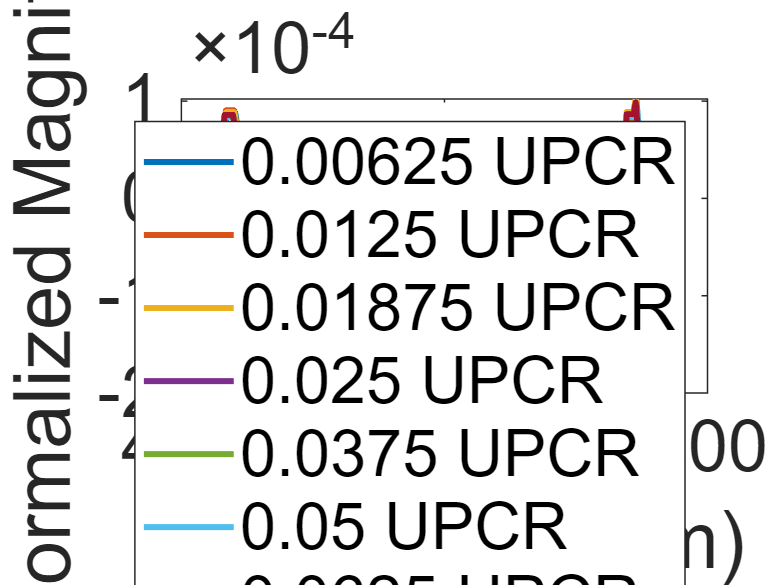


a2plot = dx2Data(indeces, :);
createFigure(wv, a2plot, labels);

classData = [];
for i=1:x
    if(lData(i) < 0.25)
        classData(i) = 1;
    
    elseif(lData(i) >= 0.25 && lData(i) <= 0.5)
        classData(i) = 2;

    else
        classData(i) = 3;
    end
end
classData = classData';

% X = sData;
%  X = pData;
% X = snvData;
% X = dxData; 
X = dx2Data;
Y = lData;
features = [pData, dxData, dx2Data];

nComponents = 50;
nFolds = 10; 
[n,p] = size(X);
%[Xl,Yl, Xs,Ys,beta,pctVar, PLSmsep] = plsregress(X,Y,nComponents, 'cv', cvpartition(length(Y),'Leaveout'));
[Xl,Yl, Xs,Ys,beta,pctVar,MSE, stats] = plsregress(X,Y,nComponents, 'CV', nFolds);
%[Xl,Yl, Xs,Ys,beta,pctVar,MSE, stats] = plsregress(X,Y,nComponents, 'cv', cvpartition(length(Y),'HoldOut',0.3));
 yfitPLS = [ones(n,1) X]*beta; 

% [PCALoadings,PCAScores,PCAVar] = pca(X,'Economy',false);
% 
% betaPCR = regress(Y-mean(Y), PCAScores(:,1:nComponents));
% betaPCR = PCALoadings(:,1:nComponents)*betaPCR;
% betaPCR = [mean(Y) - mean(X)*betaPCR; betaPCR];
% yfitPCR = [ones(n,1) X]*betaPCR;


% PCRmsep = sum(crossval(@pcrsse,X,Y,'KFold',nFolds),1) / n;
% q = mse(2,1:nFolds+1);
% plot(0:nFolds,q,'b-o',0:nFolds,PCRmsep,'r-^');
% xlabel('Number of components');
% ylabel('Estimated Mean Squared Prediction Error');
% legend({'PLSR' 'PCR'},'location','NE');


TSS = sum((Y-mean(Y)).^2);
RSS_PLS = sum((Y-yfitPLS).^2);
rsquaredPLS = 1 - RSS_PLS/TSS

rsquaredPLS = 0.6825

err_PLS = Y-yfitPLS;


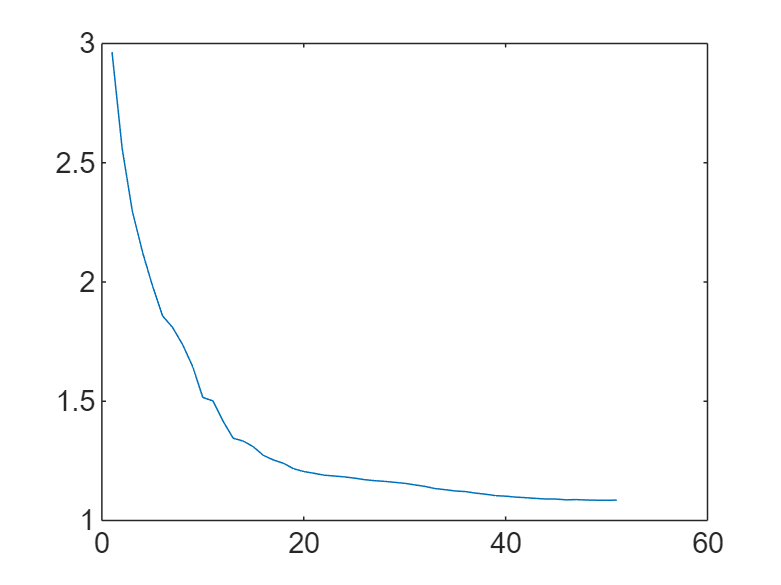

plot(MSE(2, :))

mse_pls = mean(MSE(2, :))

mse_pls = 1.3444


mse_PLS = mean(err_PLS.^2);
rmse_PLS = sqrt(mse_PLS)

rmse_PLS = 0.9698

mae_PLS = mae(err_PLS)

mae_PLS = 0.6761


% RSS_PCR = sum((Y-yfitPCR).^2);
% rsquaredPCR = 1 - RSS_PCR/TSS
% err_PCR = Y-yfitPCR;

% mse_PCR = mean(err_PCR.^2);
% rmse_PCR = sqrt(mse_PCR)
% mae_PCR = mae(err_PCR)

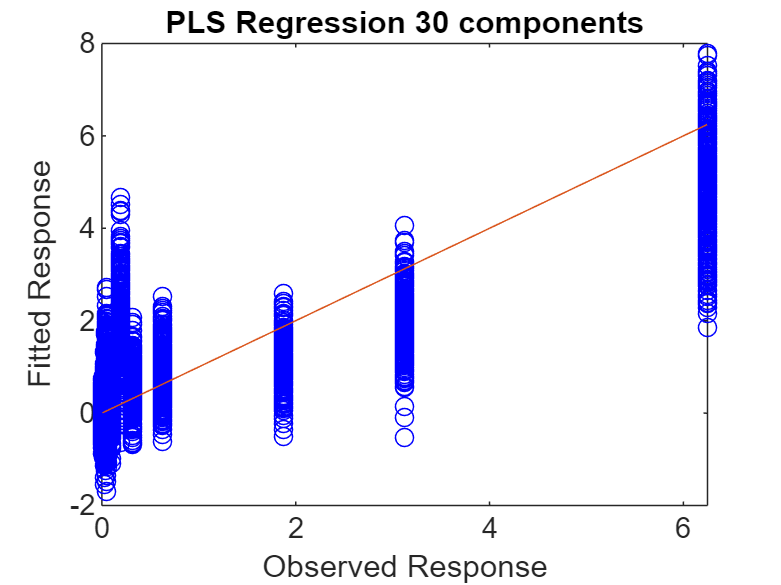

%  plot(Y,yfitPLS,'bo',Y,yfitPCR,'r^');
 plot(Y,yfitPLS,'bo', Y, Y);
 xlabel('Observed Response');
 ylabel('Fitted Response');
 % legend({'PLSR with 10 components' 'PCR with 10 Components'},'location','NW');
 title('PLS Regression 30 components');

%  plot(1:nComponents,100*cumsum(pctVar(1,:)),'b-o',1:nComponents,  ...
%  	100*cumsum(PCAVar(1:nComponents))/sum(PCAVar(1:nComponents)),'r-^');
% xlabel('Number of Principal Components');
% ylabel('Percent Variance Explained in X');
% legend({'PLSR' 'PCR'},'location','SE');

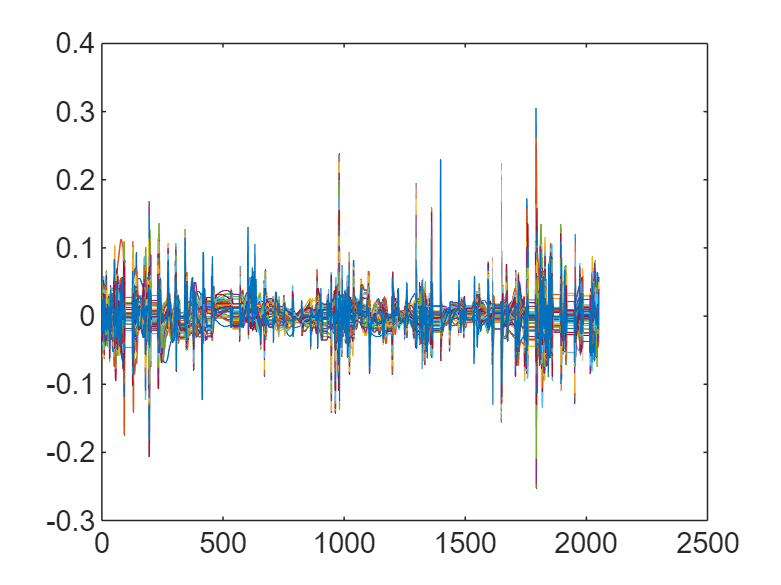

W0 = stats.W ./ sqrt(sum(stats.W.^2,1));
plot(W0,'-');


[components, idx] = sort(abs(beta), "descend");

waveLengths = (idx./y * 350) + 400 - 0.1463;


pComp = [waveLengths(1:30),components(1:30)]';
pComp = round(pComp, 2, "decimals");



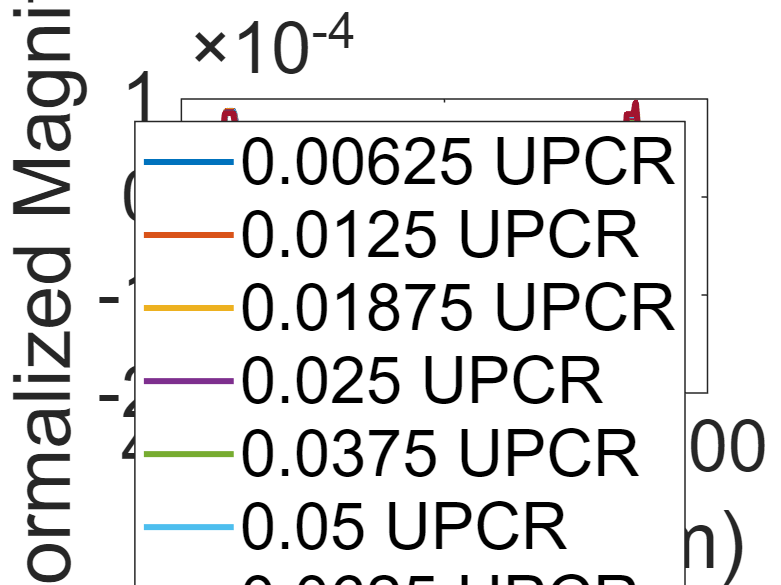

a2plot = smoothdata(X(indeces, :), "gaussian");
a2plot = smoothdata(X(indeces, :), "movmean", 10);
createFigure(wv, a2plot, labels);

sRGB = spectrumRGB(waveLengths(1:nComponents));
sRGB = squeeze(sRGB);

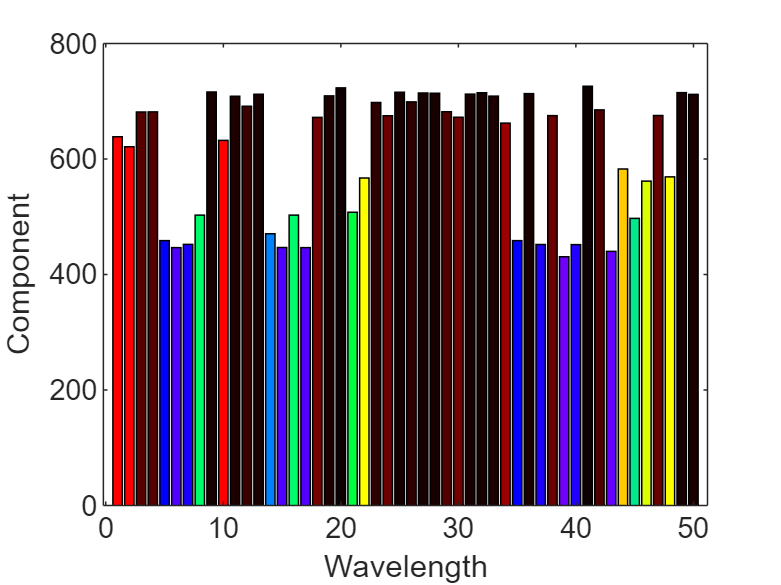


figure(1)
specBar = bar(waveLengths(1:nComponents));
specBar.FaceColor = 'flat';
for i = 1:nComponents
    bRGB = sRGB(i, :);
    specBar.CData(i, :) = bRGB;
end
xlabel('Wavelength')
ylabel('Component')